% --- 参数设置 ---
Lx = 2; % x方向长度
Ly = 1; % y方向长度
hx = 1/3; % delta x
ky = 1/5; % delta y

Nx = Lx/hx; % x方向网格数 (x0到xNx) -> 7个点, 6个间隔
Ny = Ly/ky; % y方向网格数 (y0到yNy) -> 6个点, 5个间隔

% 内部网格点索引范围
i_min = 1; i_max = Nx - 1; % i = 1, 2, 3, 4, 5
j_min = 1; j_max = Ny - 1; % j = 1, 2, 3, 4

Ni = i_max - i_min + 1; % x方向内部点数 (Ni = 5)
Nj = j_max - j_min + 1; % y方向内部点数 (Nj = 4)
M = Ni * Nj; % 总内部点数 (M = 20)

% 网格坐标
x = (0:Nx) * hx;
y = (0:Ny) * ky;

% --- 构造系数矩阵 A 和右端向量 B ---
A = zeros(M, M);
B = zeros(M, 1);

% 离散方程系数
C0 = -2/hx^2 - 2/ky^2; % -68
C_x = 1/hx^2;          % 9
C_y = 1/ky^2;          % 25

% C0 * u_ij + C_x * u_{i-1,j} + C_x * u_{i+1,j} + C_y * u_{i,j-1} + C_y * u_{i,j+1} = f_ij

% 按照 u = [u11, u21, u31, u41, u51, u12, ..., u54]' 的顺序编号
for j = j_min:j_max
    for i = i_min:i_max
        k = (j - j_min) * Ni + (i - i_min) + 1; % 线性系统中的行索引 (1 到 M)
        
        xi = x(i+1); % 网格点x坐标 (MATLAB索引从1开始, x(1)=x0, x(i+1)=xi)
        yj = y(j+1); % 网格点y坐标

        % 右端项 f(xi, yj)
        fij = xi * exp(yj);
        
        % --- 构造矩阵A和向量B ---
        
        % 主对角线上的项: C0 * u(i, j)
        A(k, k) = C0;
        
        % u(i-1, j) 项: C_x * u(i-1, j)
        if i > i_min
            A(k, k - 1) = C_x;
        else % i = i_min (i=1), 对应边界 u(0, yj)
            B(k) = B(k) - C_x * u_boundary(0, yj);
        end
        
        % u(i+1, j) 项: C_x * u(i+1, j)
        if i < i_max
            A(k, k + 1) = C_x;
        else % i = i_max (i=5), 对应边界 u(2, yj)
            B(k) = B(k) - C_x * u_boundary(2, yj);
        end
        
        % u(i, j-1) 项: C_y * u(i, j-1)
        if j > j_min
            A(k, k - Ni) = C_y;
        else % j = j_min (j=1), 对应边界 u(xi, 0)
            B(k) = B(k) - C_y * u_boundary(xi, 0);
        end
        
        % u(i, j+1) 项: C_y * u(i, j+1)
        if j < j_max
            A(k, k + Ni) = C_y;
        else % j = j_max (j=4), 对应边界 u(xi, 1)
            B(k) = B(k) - C_y * u_boundary(xi, 1);
        end
        
        % 加上右端项
        B(k) = B(k) + fij;
    end
end

% --- 求解线性系统 ---
U_vec = A \ B; % 求解 AU = B

% --- 将解向量重构为二维矩阵 ---
U = zeros(Nx + 1, Ny + 1);

% 设置边界条件
for i = 0:Nx
    xi = x(i+1);
    U(i+1, 1) = u_boundary(xi, y(1));    % u(x, 0) -> U(:, 1)
    U(i+1, Ny+1) = u_boundary(xi, y(Ny+1)); % u(x, 1) -> U(:, Ny+1)
end

for j = 0:Ny
    yj = y(j+1);
    U(1, j+1) = u_boundary(x(1), yj);    % u(0, y) -> U(1, :)
    U(Nx+1, j+1) = u_boundary(x(Nx+1), yj); % u(2, y) -> U(Nx+1, :)
end

% 填入内部解
for j = j_min:j_max
    for i = i_min:i_max
        k = (j - j_min) * Ni + (i - i_min) + 1; % 线性系统中的行索引
        U(i+1, j+1) = U_vec(k);
    end
end

% --- 显示结果 ---
disp('内部网格点近似解 U_vec:');

内部网格点近似解 U_vec:


disp(U_vec);

    0.4073
    0.8145
    1.2218
    1.6290
    2.0360
    0.4975
    0.9950
    1.4924
    1.9898
    2.4870
    0.6076
    1.2152
    1.8227
    2.4302
    3.0375
    0.7420
    1.4840
    2.2260
    2.9679
    3.7097




disp('完整的网格点解矩阵 U (行对应x，列对应y):');

完整的网格点解矩阵 U (行对应x，列对应y):


disp(U);

         0         0         0         0         0         0
    0.3333    0.4073    0.4975    0.6076    0.7420    0.9061
    0.6667    0.8145    0.9950    1.2152    1.4840    1.8122
    1.0000    1.2218    1.4924    1.8227    2.2260    2.7183
    1.3333    1.6290    1.9898    2.4302    2.9679    3.6244
    1.6667    2.0360    2.4870    3.0375    3.7097    4.5305
    2.0000    2.4428    2.9836    3.6442    4.4511    5.4366



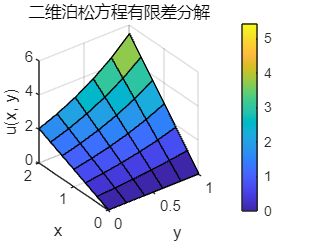


% --- 绘制解的曲面图 ---
figure;
[X_grid, Y_grid] = meshgrid(y, x); % meshgrid(y, x)是为了让surf(X, Y, Z)的x轴对应x坐标，y轴对应y坐标
surf(X_grid, Y_grid, U);
title('二维泊松方程有限差分解');
xlabel('y');
ylabel('x');
zlabel('u(x, y)');
colorbar;



% --- 边界条件函数 ---

function u_val = u_boundary(x_coord, y_coord)
    % 边界条件:
    % u(0, y) = 0
    % u(2, y) = 2*exp(y)
    % u(x, 0) = x
    % u(x, 1) = exp(1)*x
    
    Lx = 2; % 需要在函数内部重新定义或作为参数传入，这里使用硬编码以简化
    Ly = 1;

    if x_coord == 0
        u_val = 0;
    elseif abs(x_coord - Lx) < 1e-9 % 使用容差判断 x_coord == 2
        u_val = 2 * exp(y_coord);
    elseif y_coord == 0
        u_val = x_coord;
    elseif abs(y_coord - Ly) < 1e-9 % 使用容差判断 y_coord == 1
        u_val = exp(1) * x_coord;
    else
        % 理论上只应在边界点调用
        u_val = NaN;
    end
end